# Step 7: 可視化

GUILDA の図は、系統図、潮流の図、時間応答のグラフ、ばね質点モデルの 4 種類です。どの図も `plot_*` メソッドで描き、図のオブジェクト `G` を返します。描いた後の色・大きさ・時刻などの変更は、すべて `G` で行います。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

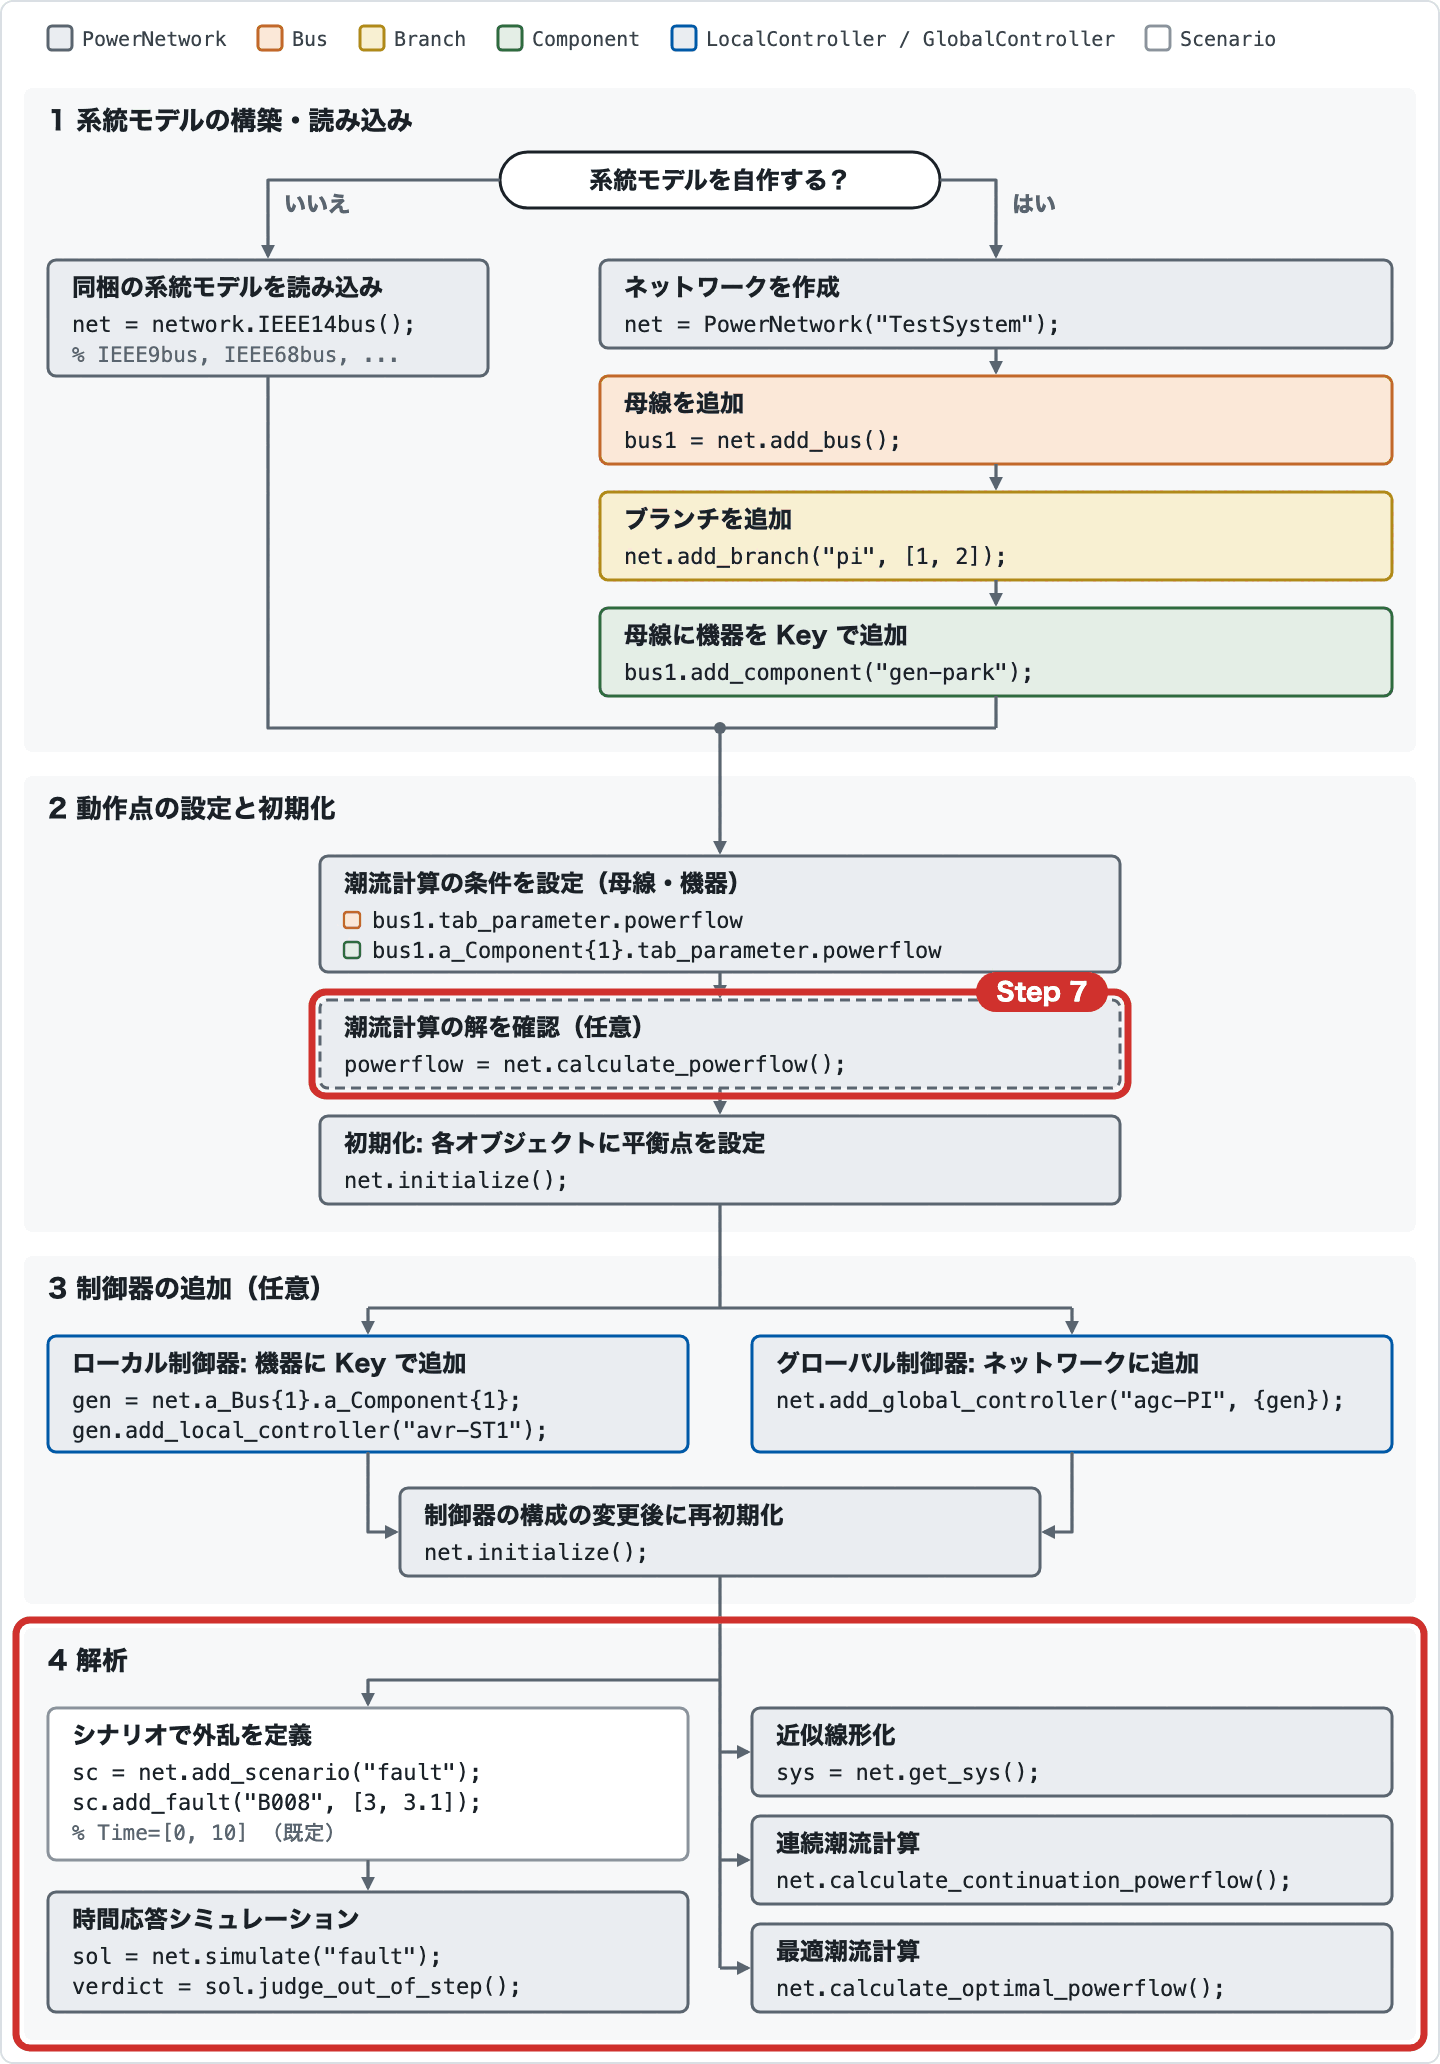

## この Step で分かること

- 系統図 `plot_diagram` の描き方（2D と 3D、色・ラベル・幅・大きさ・高さの指定、操作パネル）

- 潮流計算の結果の図（`plot_single_line_diagram`・`plot_voltage`・`plot_branch`・`plot_convergence`・`plot_diagram`）

- 時間応答の図（`plot_trajectory`、時刻つきの `plot_diagram`）

- ばね質点モデル（`plot_spring_model`、`set_time`、`link`、`animate`、`export_video`）

- 図のオブジェクト `G` の扱い（プロパティ、`set_style`、`select`、`G.ax`、`Parent`）

各節は、図を描くのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

図を描くメソッドと、返る図のクラスは次のとおりです。

## 1. 系統を用意する

同梱の IEEE 9 母線系統を読み込みます。読み込んだ時点で平衡点も求まっています。

net = network.IEEE9bus();

**注意:** 系統を編集した後は `net.initialize()` で平衡点を求め直します。`net.plot_diagram()` は、平衡点が古いときは構成だけを描きます（INFO が出ます）。

## 2. 系統図を描く: plot_diagram

`net.plot_diagram()` は、母線・ブランチ・機器を単線結線図で描きます。既定は 2D で、ブランチの色が電流 |I|、幅がブランチのアドミタンスの大きさ（アドミタンス行列の最大特異値 Ysvd）です。ブランチの上の小さな三角形は電力の流れる向きを表します（画面に表示した図では流れて動きます）。

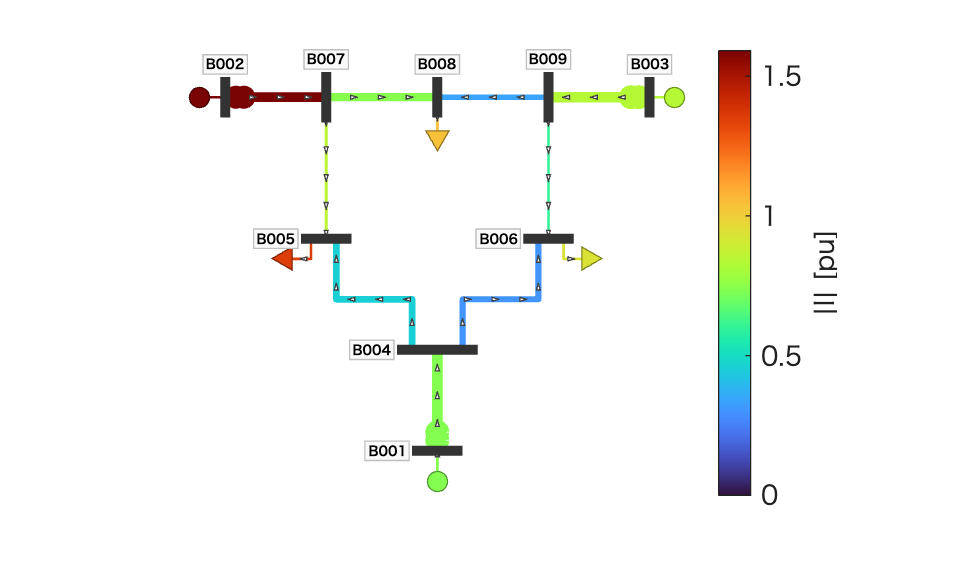

G = net.plot_diagram();

色・ラベル・幅・大きさは Name-Value で指定します。有効電力で色を付け、値をラベルにし、機器の大きさを出力の大きさにしてみます。

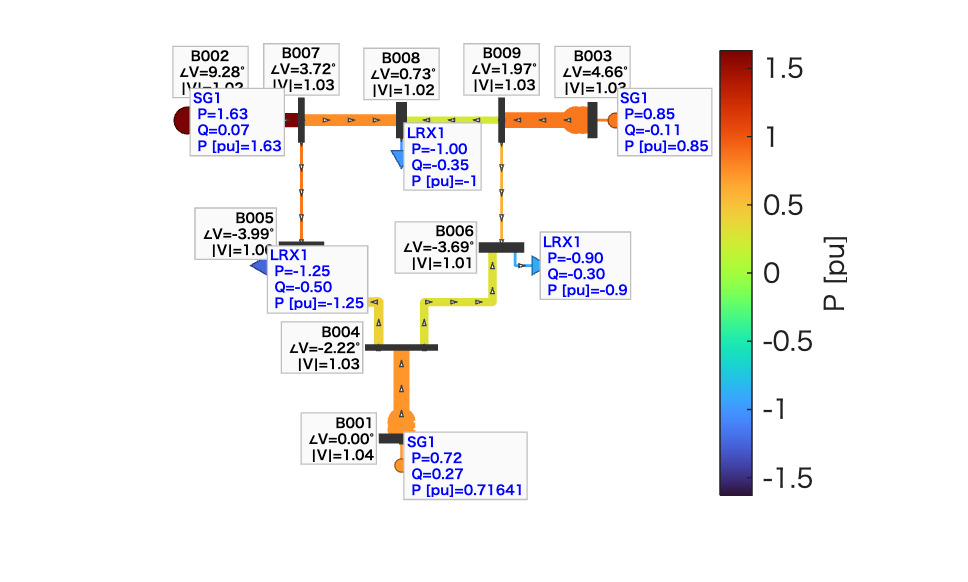

G = net.plot_diagram(ColorMode="P", LabelMode="value", MarkerSizeMode="S", BranchWidthRange=[1 6]);

ここで使ったオプションは次のとおりです。

- `ColorMode`: ブランチとリンク（機器と母線を結ぶ線）の色の量（既定 `"I"`。ここでは有効電力 `"P"`）

- `LabelMode`: ラベル（既定は母線のタグ `"bus"`。ここでは値 `"value"`）

- `MarkerSizeMode`: 母線と機器の大きさの量（既定 `"none"`。ここでは皮相電力 `"S"`）

- `BranchWidthRange`: ブランチの幅の範囲 [pt]（既定 `[1 4]`）

Name-Value の名前は、図のクラス `GraphNetDiagram` のプロパティです。選べる量の一覧と、その他のオプション（幅の量 `BranchWidthMode`、色の範囲 `ColorLimits` など）は、`GraphNetDiagram` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","class.html"),filesep,"/")+"#class=GraphNetDiagram')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。平衡点を使わずに構成だけを描く `State` などの `plot_diagram` の引数は、こちらです: [plot_diagram の引数はこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=plot_diagram')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

### 3D と高さ

`Dimension="3D"` で、同じ図を立体（直方体、管、球、円錐）で描きます。`BusHeightMode="V"` は各母線を電圧の大きさの高さに置きます。描いた後でプロパティを変えても同じです。

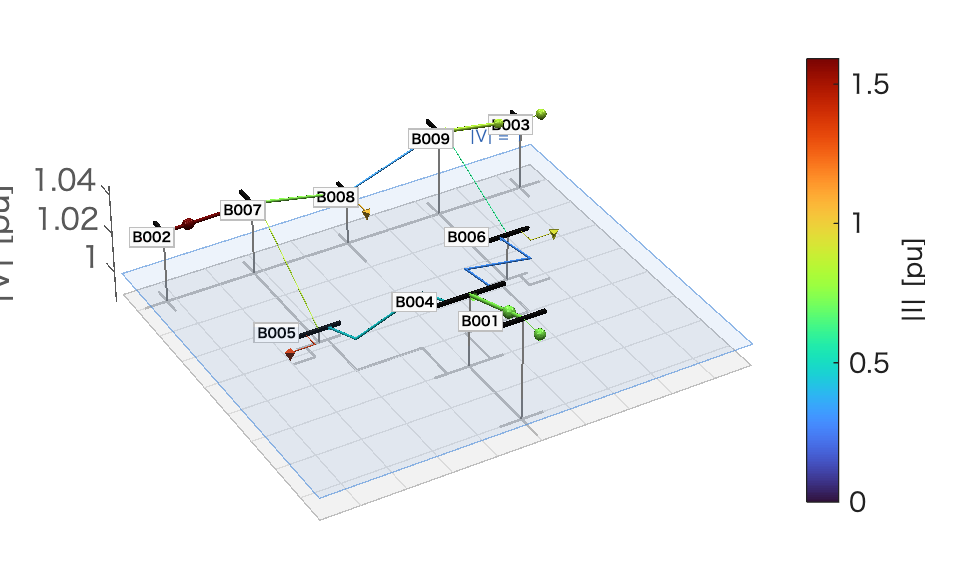

G = net.plot_diagram(Dimension="3D", BusHeightMode="V");
view(G.ax, -30, 35)

2D の図でも `BusHeightMode` は効きます。`Dimension` を変えても、同じ図のオブジェクト `G` のまま描き直します。視点を回すと高さが見えます。

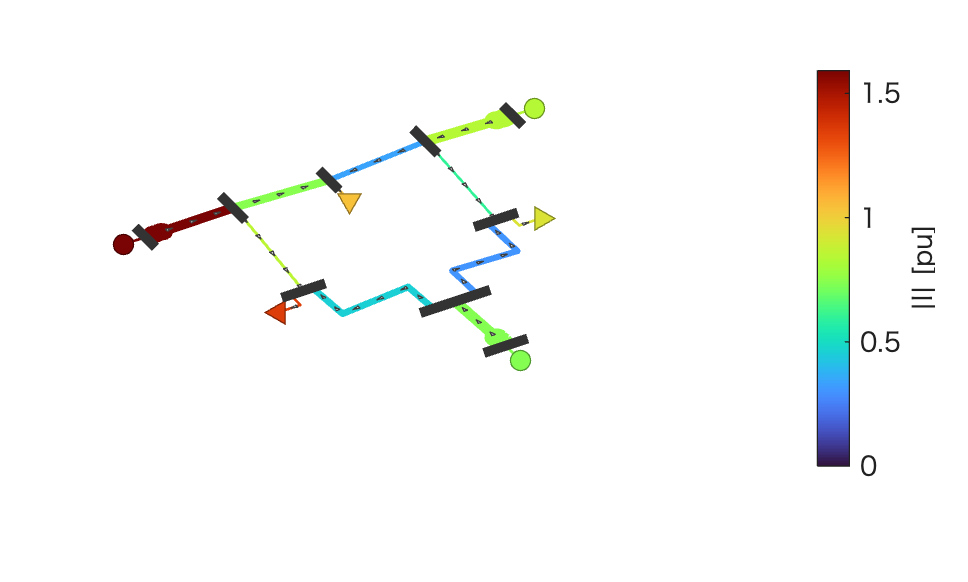

G.Dimension = "2D";
view(G.ax, -30, 35)

**注意:** 流れのアニメーションは、画面に見えている 2D の図だけで動きます。止めるには `G.FlowAnimation = false` とします。3D では円錐が流れの向きを示します。

### 操作パネル

`G.show_controls()` は、図の右に操作パネル（次元、色、ラベル、幅、高さ、流れなど）を出します。パネルは `G` のプロパティを設定するだけなので、パネルでの操作とコードでの設定は同じ結果になります。`G.hide_controls()` で消します。

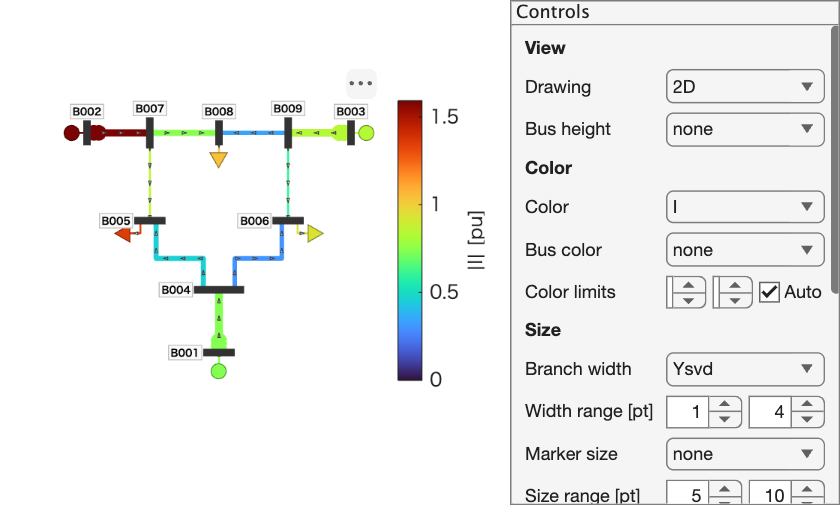

G = net.plot_diagram();
G.show_controls();

**注意:** ライブスクリプトの出力は静止画なので、パネルを操作するには図を別ウィンドウで開きます。パネルで変えたプロパティを受け取るオプションなどは、`show_controls` のリファレンスにあります: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=GraphBase&method=show_controls')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 3. 図のオブジェクト G の扱い

どの `plot_*` も図のオブジェクト `G` を返します。`G` で次のことができます。

- オプションの変更: Name-Value の名前はすべて `G` のプロパティで、設定すると図が変わります。

- 要素ごとの見た目: `G.tab_element` に要素（タグ、種類、番号）があり、`G.set_style(タグ, Color=..., LineWidth=..., Label=..., Visible=...)` でタグごとに変えます。`G.reset_style()` で元に戻します。

- 選択: `G.select(タグ)` で選択色（`SelectionColor`）の重ね描きをし、`G.clear_selection()` で消します。

- MATLAB の軸: `G.ax` が軸（axes）で、`title` や `axis`、`exportgraphics` などにそのまま使えます。

要素のタグは、系統の要素のタグと同じです。ブランチ EL004（母線 B004–B005）を太い赤にして、発電機を選択してみます。

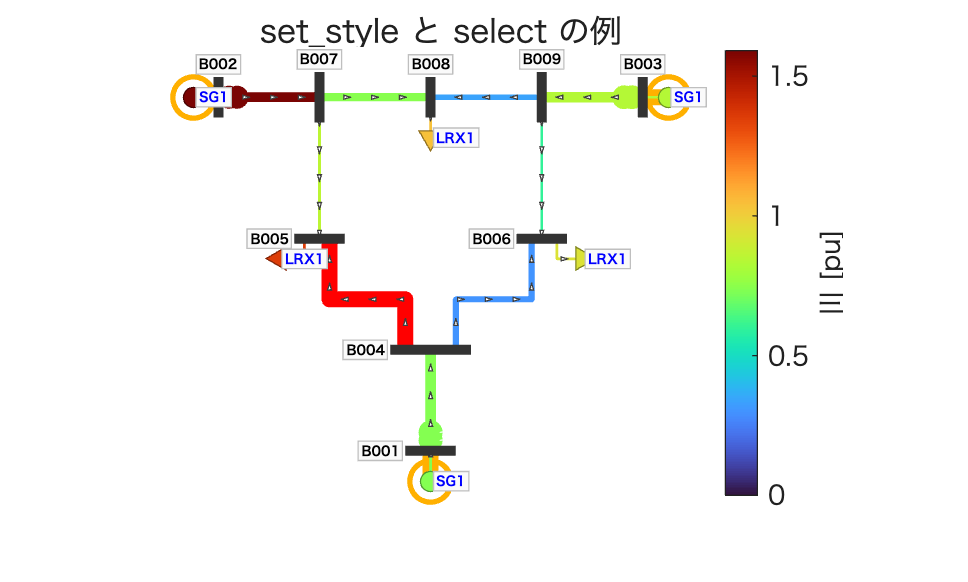

G = net.plot_diagram(LabelMode="tag");
G.set_style("EL004", Color="r", LineWidth=6);
G.select(["B001SG1", "B002SG1", "B003SG1"]);
title(G.ax, "set_style と select の例", Interpreter="none")

**確かめる（省略できます）**

図の要素の表と、選択している要素を表示します。種類（`Kind`）は `"bus"`、`"branch"`、`"component"`、`"link"` です。系統のブランチのタグと両端の母線は `net.get_element_table` で確かめられます（Step 3）。

head(G.tab_element, 8)

     Tag      Kind     Index
    ______    _____    _____

    "B001"    "bus"      1  
    "B002"    "bus"      2  
    "B003"    "bus"      3  
    "B004"    "bus"      4  
    "B005"    "bus"      5  
    "B006"    "bus"      6  
    "B007"    "bus"      7  
    "B008"    "bus"      8  



G.Selection

ans = 1×3 の string 配列
    "B001SG1"    "B002SG1"    "B003SG1"


net.get_element_table(Kind="branch")

ans = 9×12 table
               Tag        Kind            Key                    Class             Role    Bus    Parent     From       To      State    Input    Output
             _______    ________    ________________    _______________________    ____    ___    ______    ______    ______    _____    _____    ______

    ET001    "ET001"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B001"    "B004"     ""       ""        ""  
    ET002    "ET002"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B002"    "B007"     ""       ""        ""  
    ET003    "ET003"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B003"    "B009"     ""       ""        ""  
    EL004    "EL004"    "branch"    "pi"                "branch.pi"                 ""     ""       ""      "B004"    "B005"     ""       ""        ""  
    EL005    "EL005"    "branch"    "pi"                "branch.

**注意:** 要素をクリックしたときの処理は `G.ElementClickedFcn = @(G, data) disp(data.Tag)` のように登録します。

### 描く場所を指定する: Parent

`Parent` に figure・uipanel・tiledlayout の入った容器などを渡すと、その中に描きます。1 パネルの図なら axes にも描けます。2 つの図を並べてみます。

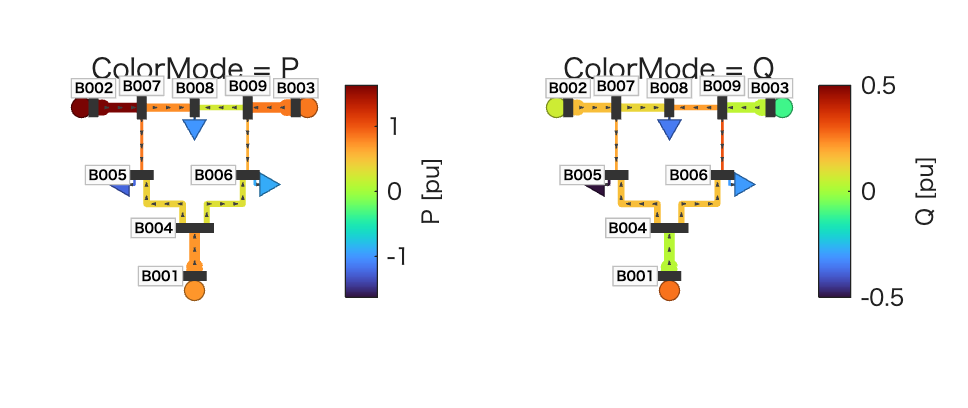

fig = figure(Position=[100 100 900 380]);
tl = tiledlayout(fig, 1, 2);
G1 = net.plot_diagram(Parent=nexttile(tl), ColorMode="P");
G2 = net.plot_diagram(Parent=nexttile(tl), ColorMode="Q");
title(G1.ax, "ColorMode = P"); title(G2.ax, "ColorMode = Q");

## 4. 潮流計算の結果の図

`calculate_powerflow` の結果（`ResultPF`）には、潮流を見るための図がまとまっています。

res_pf = net.calculate_powerflow(WarmStart=false);

### plot_single_line_diagram: 論文用の単線結線図

論文に載せる白黒の単線結線図を、2 段組の論文の 1 段の幅（8.5 cm）で描きます。色や流れの点はなく、指定できるのは描く場所の `Parent` だけです。

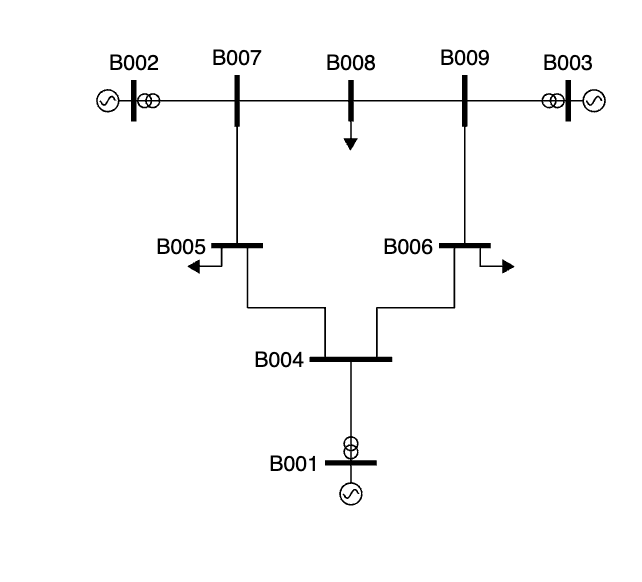

G = res_pf.plot_single_line_diagram();

母線を電圧で塗り、潮流の向きを流れの点で示す図は `plot_diagram(BusColorMode="V", ColorMode="none")` で描けます。母線の色を位相にする `BusColorMode`、流れの点を無効電力にする `FlowMode` などのオプションは、`plot_diagram` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultPF&method=plot_diagram')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

### plot_voltage と plot_branch

`plot_voltage` は母線電圧の大きさと位相の棒グラフで、点線は運転の上下限（`Vmin`・`Vmax`）です。

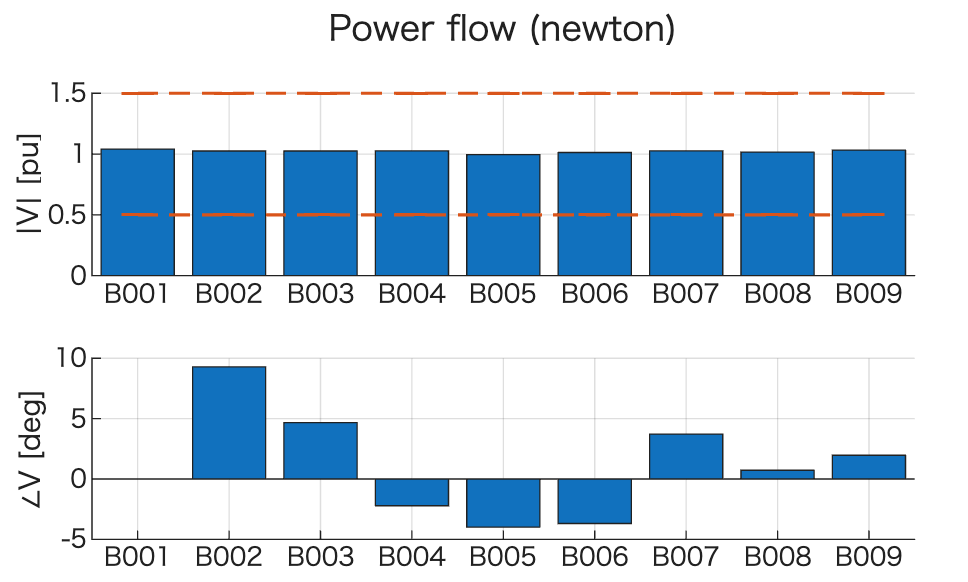

G = res_pf.plot_voltage();

大きさだけを描く、上下限を描かない、などのオプションは、`plot_voltage` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultPF&method=plot_voltage')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

`plot_branch` はブランチごとの流れの棒グラフです。`Quantity` で量を選びます。ここでは損失 `"loss"` を描きます（既定は有効電力 `"P"`）。

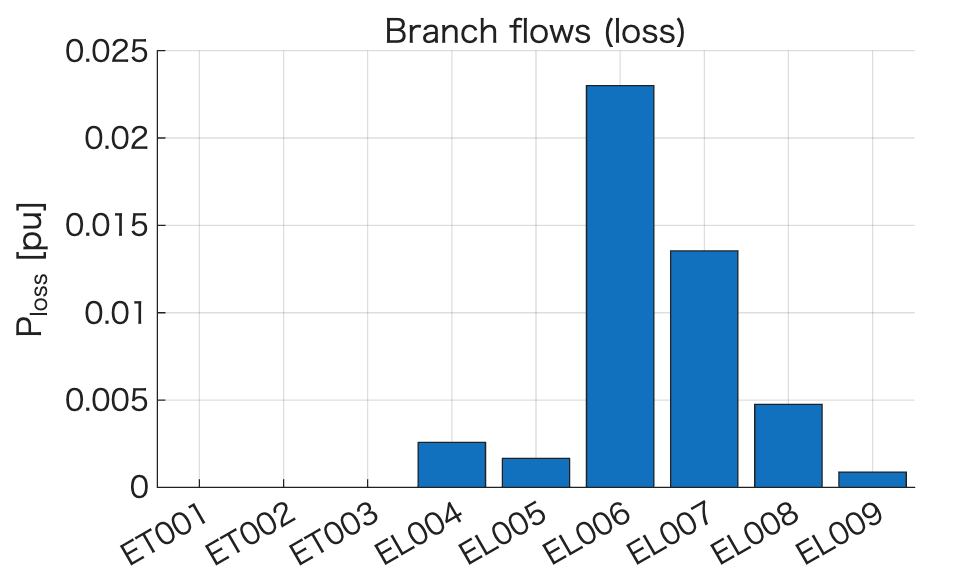

G = res_pf.plot_branch(Quantity="loss");

`Quantity` で選べる量（`"Q"`、`"S"`、`"loading"` など）は、`plot_branch` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultPF&method=plot_branch')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

### plot_convergence と plot_diagram

`plot_convergence` は潮流計算の反復ごとの不平衡量（収束の様子）です。ここでは前回の解から始めない（`WarmStart=false`）で計算したので、反復が見えます。

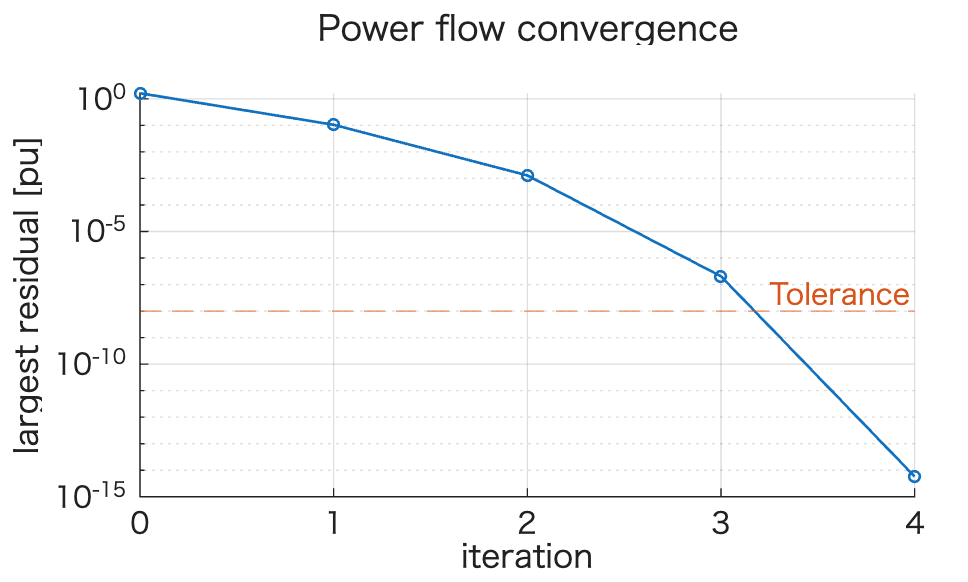

G = res_pf.plot_convergence();

`plot_diagram` は潮流の解を系統図で描きます。オプションは `net.plot_diagram` と同じです。

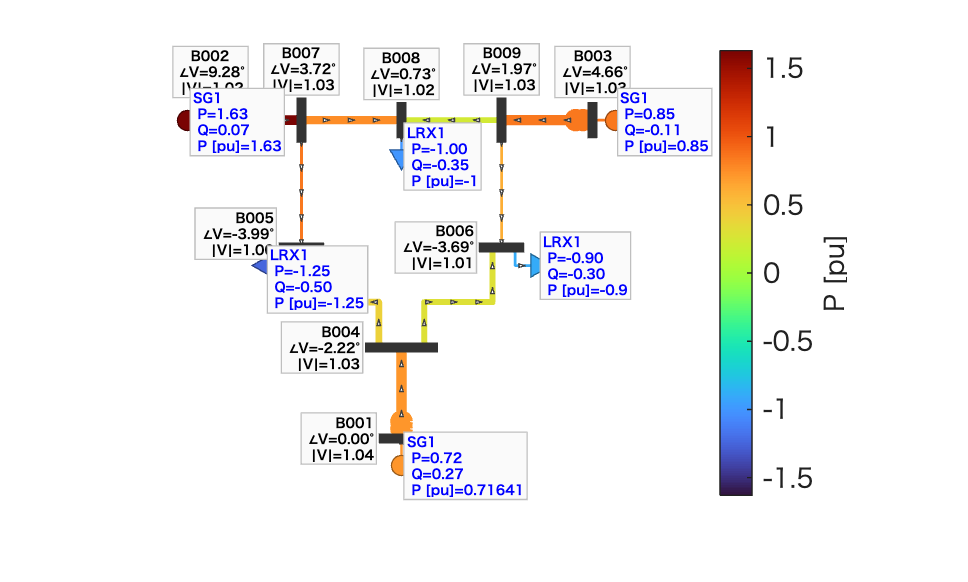

G = res_pf.plot_diagram(ColorMode="P", LabelMode="value");

## 5. 時間応答の図

母線 B007 で 1 秒から 0.05 秒間の地絡を起こすシナリオで、5 秒間シミュレーションします（シナリオの作り方は Step 5）。

sc = net.add_scenario("fault");
sc.add_fault("B007", [1, 1.05]);
res = net.simulate("fault", Time=[0, 5]);

### plot_trajectory

`plot_trajectory` は時間応答のグラフです。既定は全母線の電圧の大きさです。`Quantity` に機器の状態や入力の名前を指定すると、その量を描きます。ここでは発電機の周波数偏差 `"omega"` を描きます。

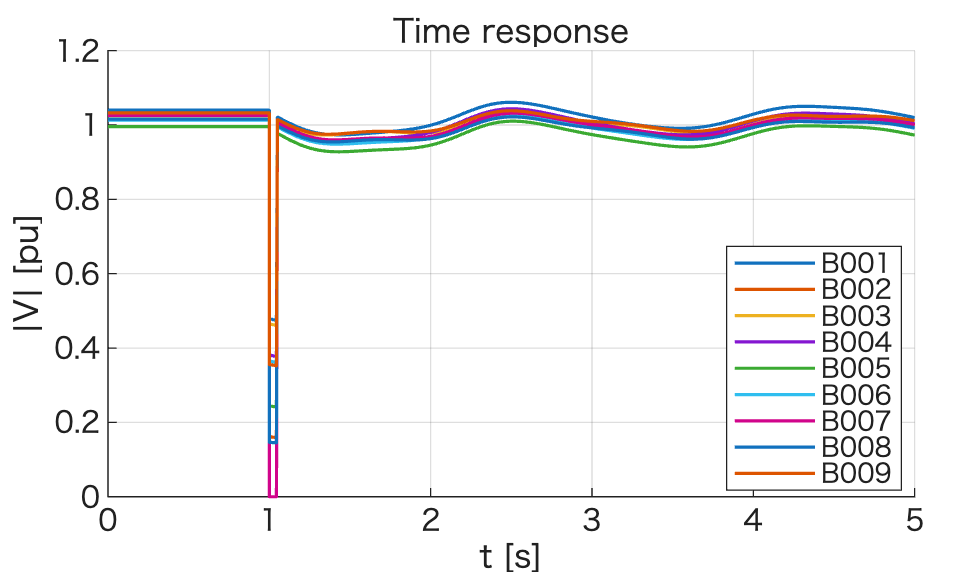

G = res.plot_trajectory();

G = res.plot_trajectory(Quantity="omega");

線は母線や機器のタグを持つ要素なので、`set_style` で強調できます。`G.set_time(t)` は時刻 t にカーソルを引きます。

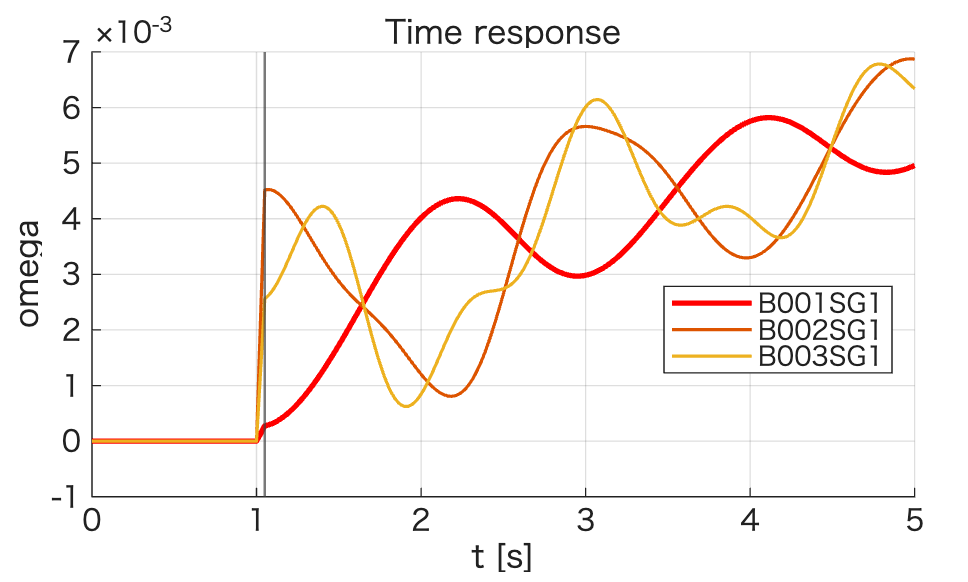

G.set_style(G.tab_element.Tag(1), Color="r", LineWidth=2);
G.set_time(1.05);

`Quantity` で選べる量と、描く母線を選ぶオプションなどは、`plot_trajectory` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultODE&method=plot_trajectory')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

### 時刻つきの系統図

`ResultODE.plot_diagram` は全時刻の値を持つ系統図です。`G.set_time(t)` で、その時刻の色・幅・流れを表示します。地絡中（1.02 秒）を見てみます。

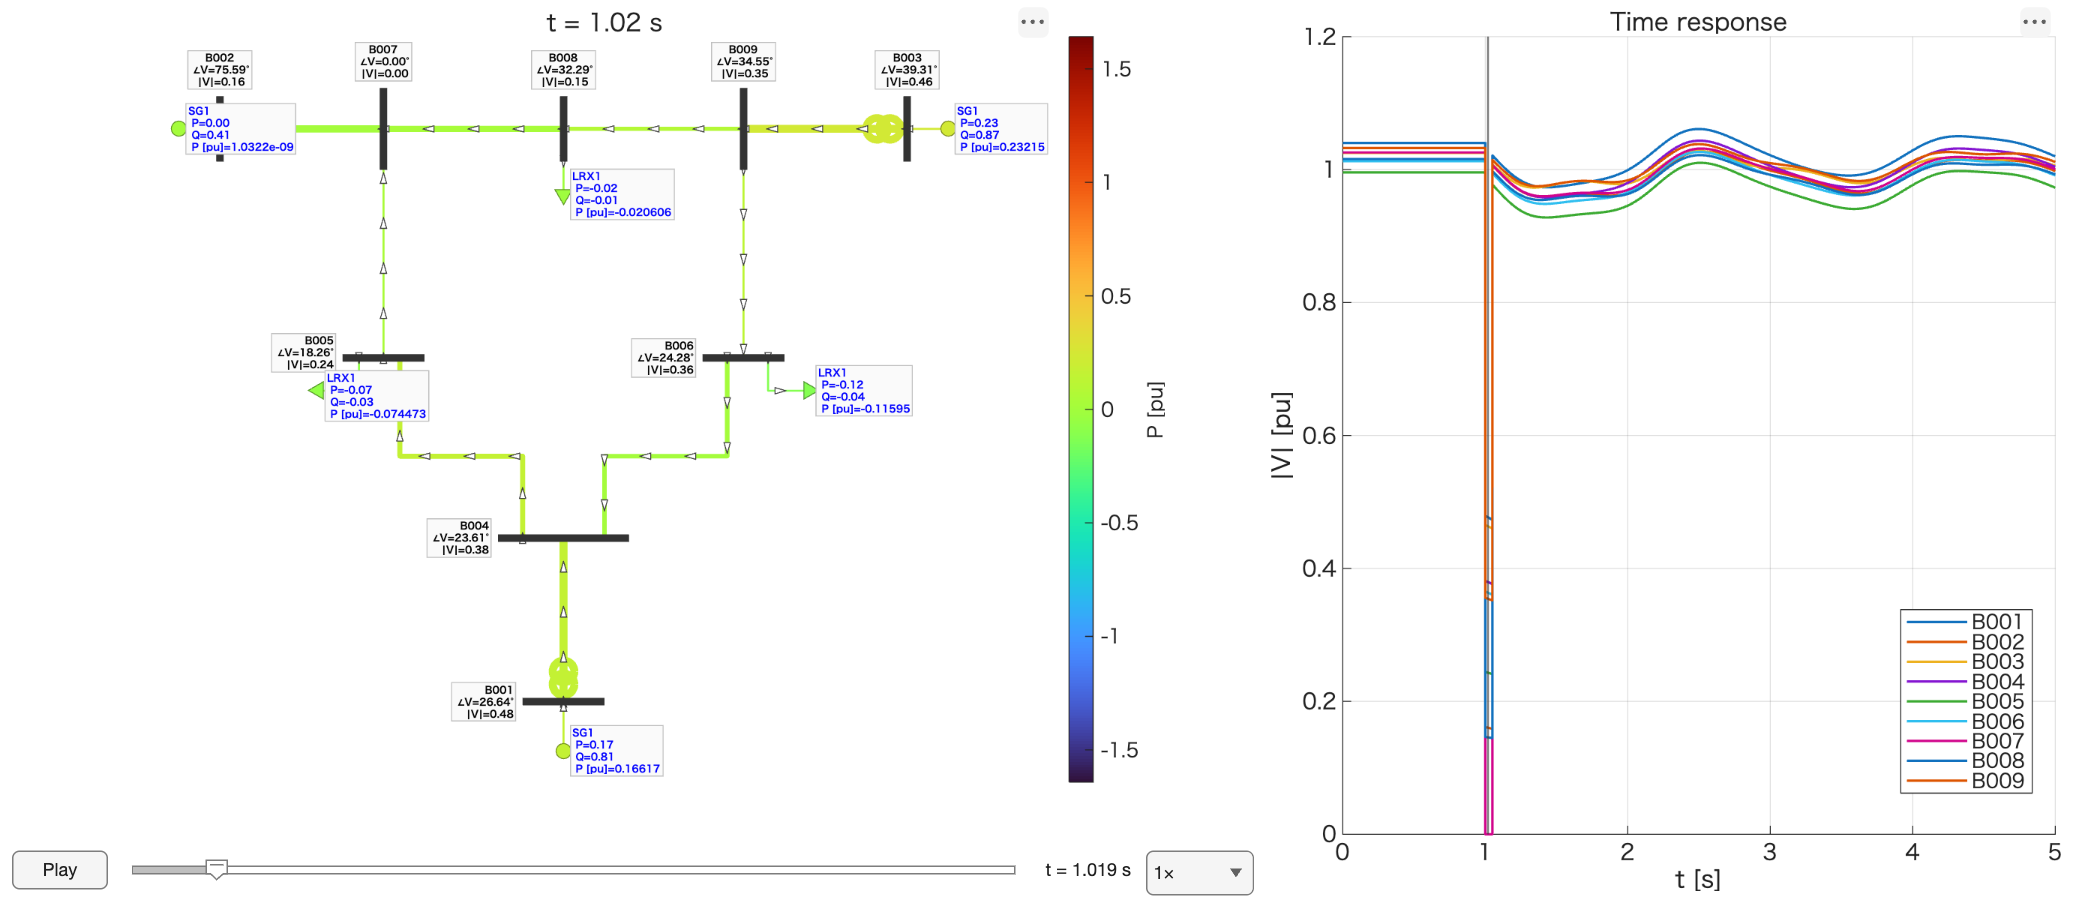

G = res.plot_diagram(ColorMode="P", LabelMode="value");
G.set_time(1.02);

**注意:** 色や幅の尺度は全時刻で 1 つなので、どの時刻でも同じ色は同じ量を表します。範囲を固定するオプション（`ColorLimits`）などは、`GraphNetDiagram` のリファレンスにあります: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","class.html"),filesep,"/")+"#class=GraphNetDiagram')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 6. ばね質点モデル

`plot_spring_model` は、電圧のフェーザを点、送電線と発電機のリアクタンスをばねとして描きます。矢印は有効電力 P と無効電流 Iq です。平衡点は `net.plot_spring_model`、潮流の解は `res_pf.plot_spring_model`、時間応答は `res.plot_spring_model` で描きます。

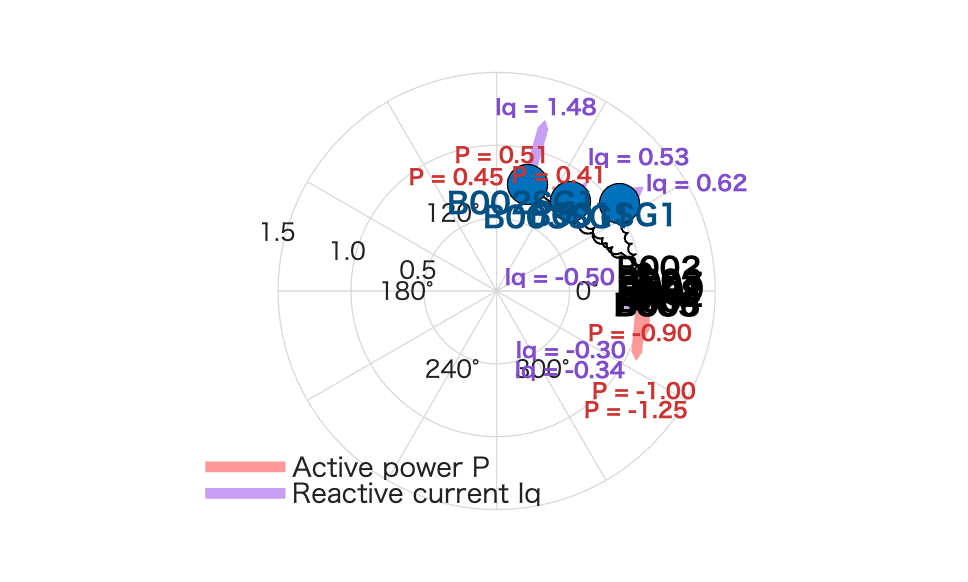

G = net.plot_spring_model();

`Dimension=3` で、曲面 z = log|V| の上に描きます。

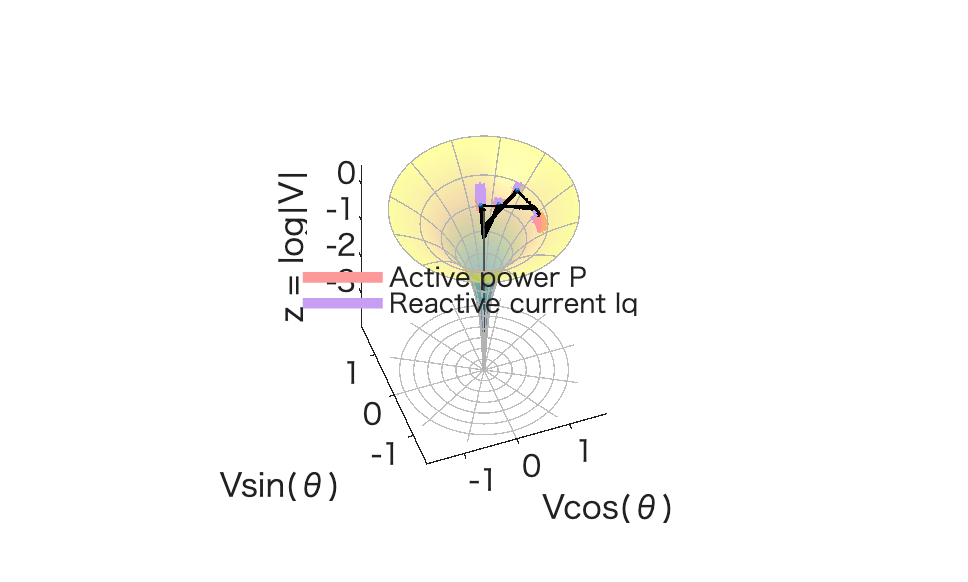

G = net.plot_spring_model(Dimension=3);

### 時刻を動かす: set_time・link・animate

時間応答のばね質点モデルは全時刻を持ちます。`set_time` で時刻を選び、`link` でほかの図（`plot_trajectory` のカーソルなど）と時刻を連動させます。

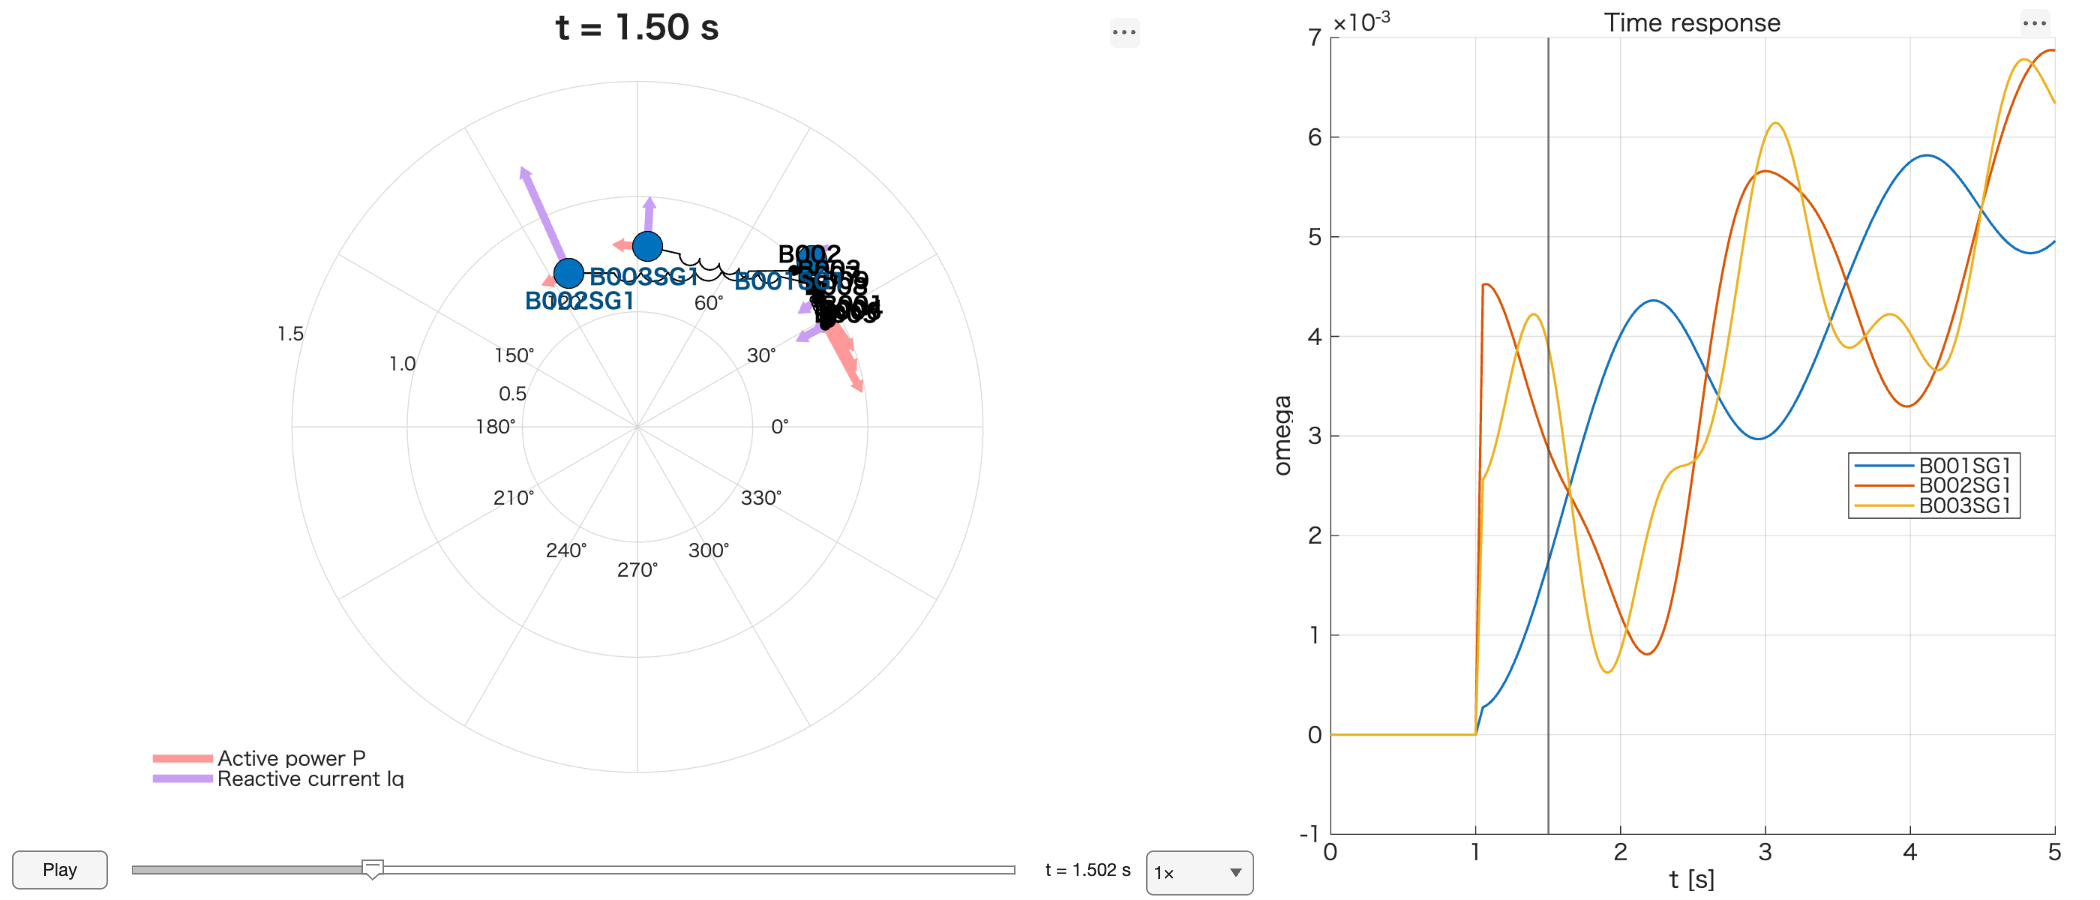

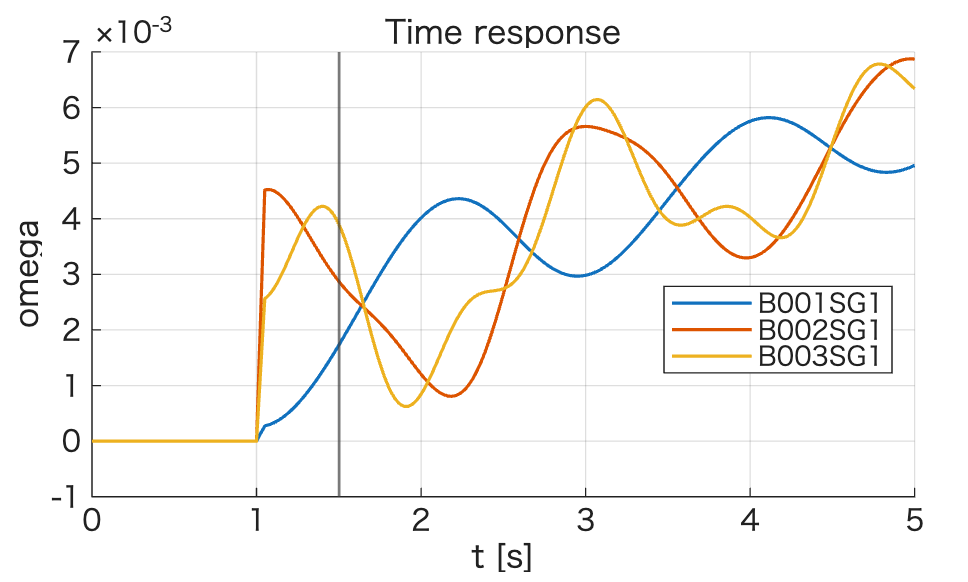

S = res.plot_spring_model();
S.ShowValue = false;    % 矢印の値を消して見やすくする
Gt = res.plot_trajectory(Quantity="omega");
S.link(Gt);
S.set_time(1.5);       % 両方の図が 1.5 秒を表示する

`S.animate()` は図の中で時間応答を再生します。`S.export_video(ファイル名)` は同じ再生を MP4 の動画に書き出します。ここでは、1 秒あたりのこまの数 `FrameRate`、こまを取るデータの時間の間隔 `TimeStep`（秒）、最後のこまを止めておく時間 `HoldTime`（秒）を指定します。

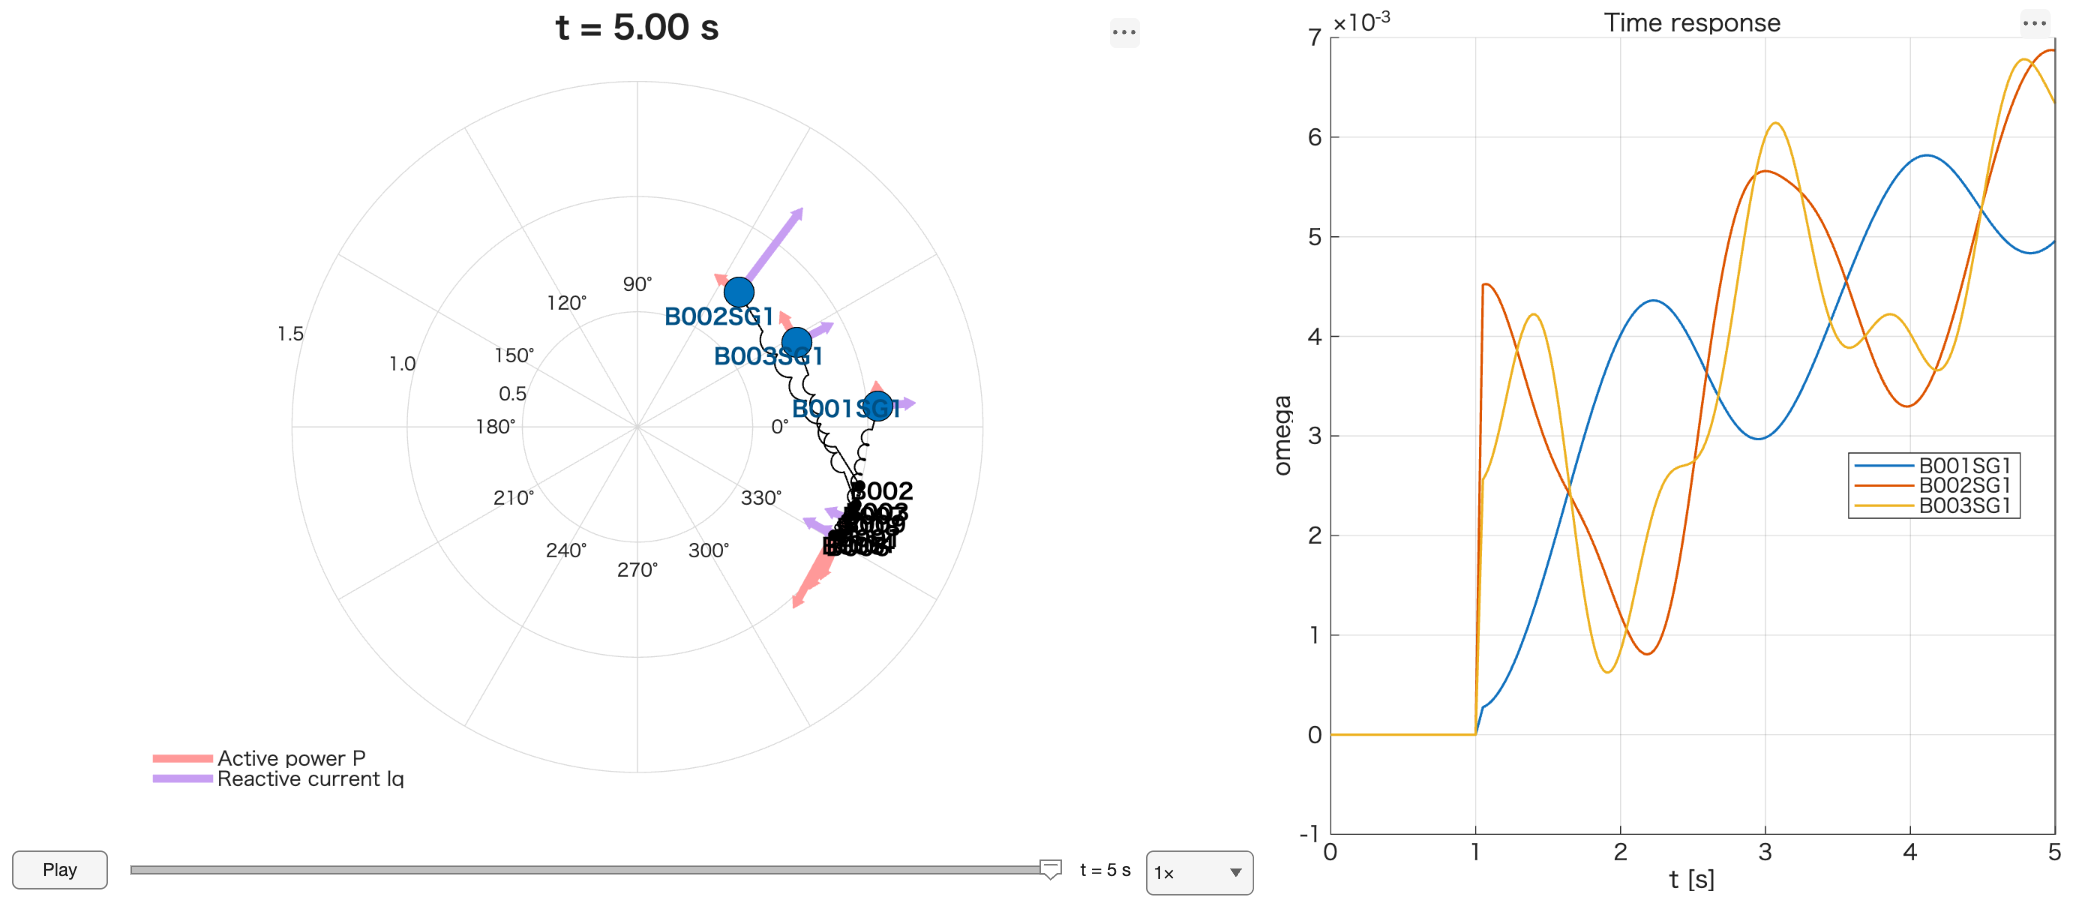

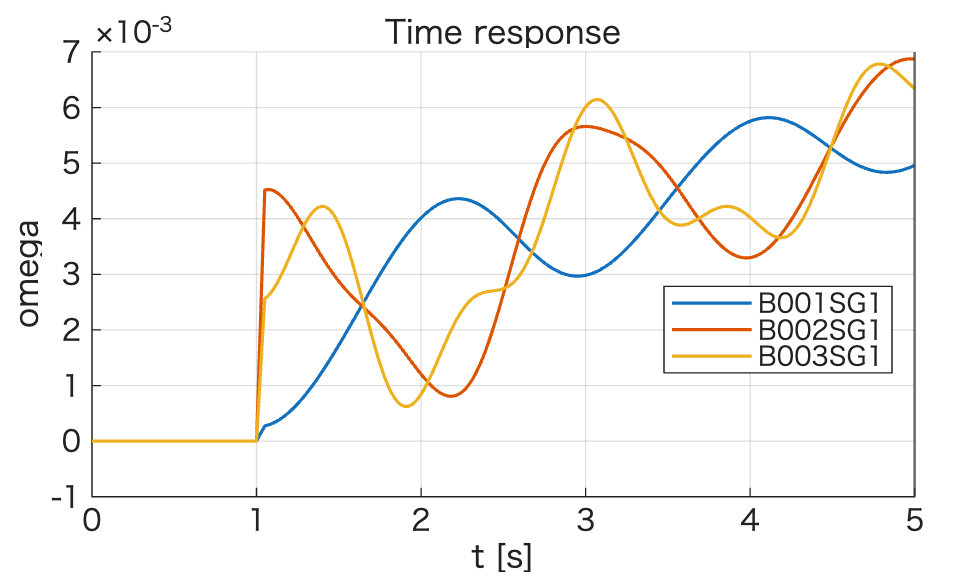

s_video = fullfile(tempdir, "Step7_spring.mp4");
S.export_video(s_video, FrameRate=20, TimeStep=0.1, HoldTime=0);

**確かめる（省略できます）**

動画のファイルができたかを確かめます。

isfile(s_video)

ans = logical
   1


**注意:** `animate` と `export_video` はどの図のクラスにもあり、時刻を持つ系統図（`res.plot_diagram`）でも使えます。その他のオプション（再生の速さ、軸だけの記録など）は、`animate`・`export_video` のリファレンスで確かめられます: [animate のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=GraphBase&method=animate')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）・[export_video のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=GraphBase&method=export_video')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。ばね質点モデルの見た目を変えるプロパティは、クラスのページにあります: [GraphSpring2D のプロパティはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","class.html"),filesep,"/")+"#class=GraphSpring2D')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 7. ほかの解析の図

近似線形化と最適潮流計算の結果にも図があります。使い方はそれぞれの Step で説明します。

- 固有値の地図 `ResultLIN.plot_eigenvalue`（Step 8）

- 出力と電圧の棒グラフ `ResultOPF.plot_dispatch`、限界価格の系統図 `ResultOPF.plot_lmp`、反復の様子 `ResultOPF.plot_iteration`（Step 9）

- 連続潮流計算の PV 曲線 `plot_pvcurve`（Step 10）

## 次の Step

- 次は Step 8: 近似線形化です。

- ばね質点モデルで系統の動きを読む方法は Part 4: ばね質点モデルで学びます。

[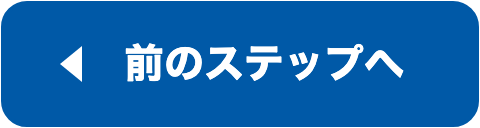](matlab:open('Step6_SimulationResult.mlx'))　　[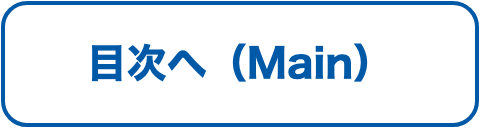](matlab:open('Main.mlx'))　　[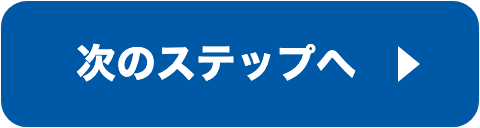](matlab:open('Step8_Linearization.mlx'))